# Atividade 09_01

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Limiarização global automática (método de Otsu, função graythresh)    

Segmentar as lesões de pele pigmentadas (pigmented skin lesion) das imagens mostradas abaixo [[CS], Figura 6] utilizando limiarização global automática pelo método de Otsu (função *graythresh*). **Nas imagens de saída, os pixels ‘1’ (brancos) devem corresponder ao objeto e ‘0’ (pretos) ao fundo.** As imagens mostradas são coloridas. As versões destas imagens disponíveis para esta atividade, psl1_gray.png, psl2_gray.png e psl3_gray.png, já foram convertidas para níveis de cinza. Importante: conforme [CS] e diversos outros autores, a segmentação de qualidade de lesões de pele pigmentadas é difícil de ser obtida. A solução sugerida nesta atividade tem fins didáticos, não científicos.

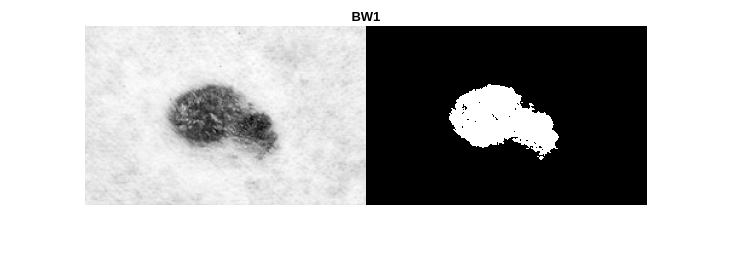

f1 = imread("psl1_gray.png");
f2 = imread("psl2_gray.png");
f3 = imread("psl3_gray.png");

th1 = graythresh(f1);
th2 = graythresh(f2);
th3 = graythresh(f3);

bw1 = 1 - imbinarize(f1, th1);
bw2 = 1 - imbinarize(f2, th2);
bw3 = 1 - imbinarize(f3, th3);

thp1 = th1 * 255;
thp2 = th2 * 255;
thp3 = th3 * 255;

figure, imshowpair(f1, bw1, "montage")
title("BW1")

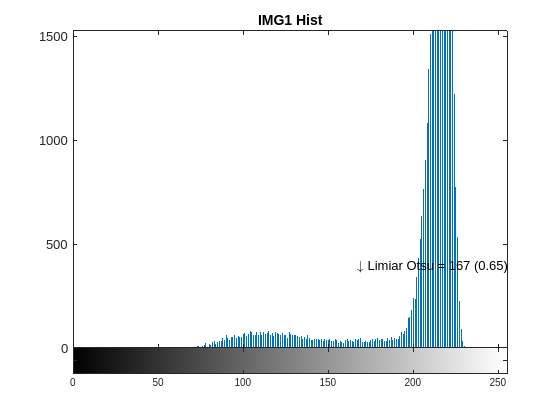


figure, imhist(f1)
title("IMG1 Hist")
text(thp1, 400, ['\downarrow', ' Limiar Otsu = ', num2str(thp1) , ' (' num2str(th1, 2) ')'])

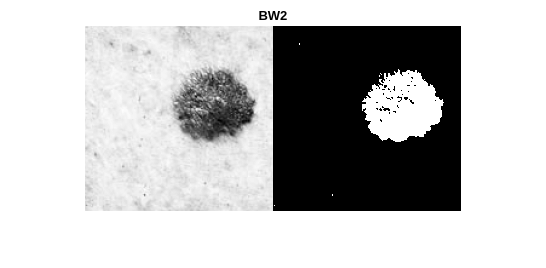


figure, imshowpair(f2, bw2, "montage")
title("BW2")

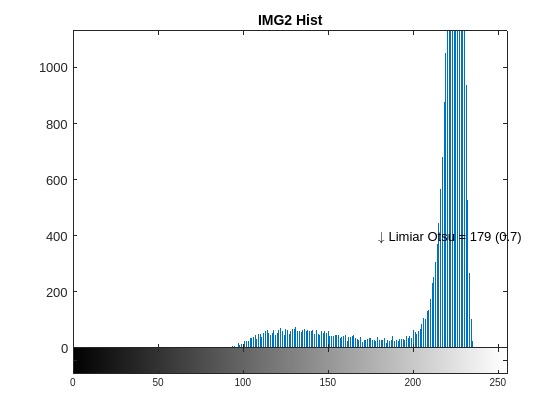


figure, imhist(f2)
title("IMG2 Hist")
text(thp2, 400, ['\downarrow', ' Limiar Otsu = ', num2str(thp2) , ' (' num2str(th2, 2) ')'])

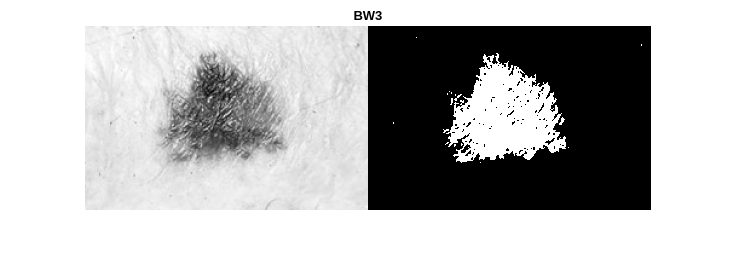


figure, imshowpair(f3, bw3, "montage")
title("BW3")

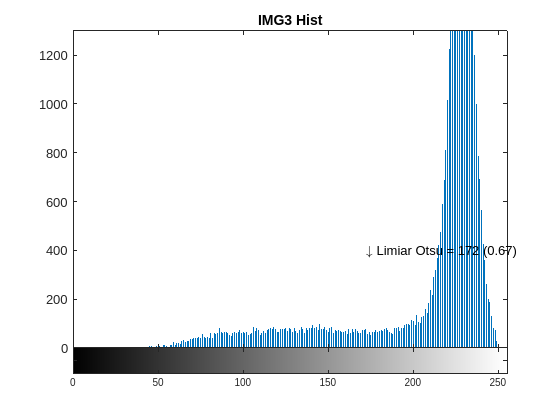


figure, imhist(f3)
title("IMG3 Hist")
text(thp3, 400, ['\downarrow', ' Limiar Otsu = ', num2str(thp3) , ' (' num2str(th3, 2) ')'])